# Problem 1

clc;
clear;
close all;

## Part A,B,C - See Written Portion

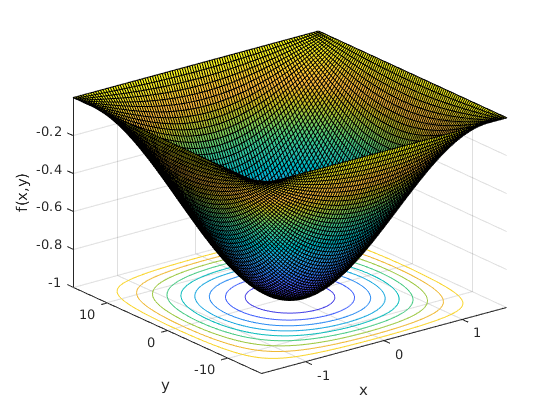

% define the function to minimize
f = @(x,y) -cos(x).*cos(y/10);

% define the domain
x = linspace(-pi/2,pi/2,100);
y = linspace(-10*pi/2,10*pi/2,100);
[xx,yy] = meshgrid(x,y);

% plot the function
figure;
surfc(xx,yy,f(xx,yy));
xlabel('x'); ylabel('y'); zlabel('f(x,y)');

## Part D and E

% run descent methods
descent_methods(1,1); % Random Point

Gradient Descent w/ exact line search optimum: x = 0, y = 9.904e-05 @ iteration 918
Gradient Descent w/o line search optimum: x = 0, y = 9.9979e-05 @ iteration 917
Newton Method w/ exact line search optimum: x = 1.9367e-07, y = 7.3013e-08 @ iteration 22
Newton Method w/o line search optimum: x = 1.5708, y = 832.5222 @ iteration 575


descent_methods(-pi/4,pi/2); % In Positive-Definite Interval

Gradient Descent w/ exact line search optimum: x = 0, y = 9.9922e-05 @ iteration 962
Gradient Descent w/o line search optimum: x = 0, y = 9.9858e-05 @ iteration 962
Newton Method w/ exact line search optimum: x = -3.7842e-08, y = 3.393e-08 @ iteration 60
Newton Method w/o line search optimum: x = -1.5708, y = -361.2831 @ iteration 973


descent_methods(-pi/2,pi/2); % Not in Positive-Definite Interval

Gradient Descent w/ exact line search optimum: x = 0, y = 9.9791e-05 @ iteration 963
Gradient Descent w/o line search optimum: x = 0, y = 9.9727e-05 @ iteration 963
Newton Method w/ exact line search optimum: x = -1.5708, y = 2.2498 @ iteration 1000
Newton Method w/o line search optimum: x = -1.5708, y = 15.7075 @ iteration 1000


descent_methods(1,3); % In Positive-Definite Interval (showing restricted radius of convergence for non-line search)

Gradient Descent w/ exact line search optimum: x = 0, y = 0.00013123 @ iteration 1000
Gradient Descent w/o line search optimum: x = 0, y = 0.00013114 @ iteration 1000
Newton Method w/ exact line search optimum: x = 3.7823e-08, y = 9.6786e-08 @ iteration 72
Newton Method w/o line search optimum: x = -6.2832, y = 3539.2929 @ iteration 1000


## Part F

We note that the rate of convergence of Newton's method is much faster than the method of steepest descent. However, steepest descent converges to the minimum of the function from any initial point, while Newton's method can only converge from where the initial point is in the positive-definite interval of the function. We also note that the line search does not affect the convergence of steepest descent by much. For Newton's method, however, the line search seems to be a necessary component as without it, Newton's method seems to converge to points outside the desired domain of the function. Additionally, the line search causes Newton's method to converge much faster than without it.

function [c,v_sd_ne,v_sd_e,v_nm_ne,v_nm_e] = descent_methods(x0,y0)
% descent_methods - function defining descent methods to run on data
%        runs steepest descent and newton method w/ and w/o line search

    % define the function to minimize
    f = @(x,y) -cos(x).*cos(y/10);

    % define search direction for steepest descent (from 1C)
    pk_sd = @(x,y) [-sin(x).*cos(y/10); -0.1*cos(x).*sin(y/10)];
    
    % define search direction for newton method (from 1C)
    pk_nm = @(x,y) [(-0.5*sin(2*x).*(cos(y/10).^2 + 0.1*sin(y/10).^2))./(cos(x-y/10).*cos(x+y/10));...
                    (-0.5*sin(y/5).*(0.1*sin(x).^2 + 100*cos(x).^2))./(cos(x-y/10).*cos(x+y/10))];

    % run line search algorithms
    % set initial vectors
    v_sd_ne = [x0;y0];
    v_sd_e = [x0;y0];
    v_nm_ne = [x0;y0];
    v_nm_e = [x0;y0];
    % set alpha values for no line search (this probably can be omitted...)
    a_sd_ne = 1;
    a_nm_ne = 1;
   
    % save iteration # on convergence when norm of descent vector < 10^-6
    lim = 1e-6;
    c = [0,0,0,0];
    
    % descent loop
    for n=1:1000
        % steepest descent with no line search
        pk = pk_sd(v_sd_ne(1),v_sd_ne(2));
        if (norm(pk) > lim)
            v_sd_ne = v_sd_ne + a_sd_ne*pk;        
            c(1) = c(1) + 1;
        end
        
        % steepest descent with exact line search
        x = v_sd_e(1); y = v_sd_e(2);
        pk = pk_sd(x,y);
        if (norm(pk) > lim)
            fes = @(a) f(x+a*pk(1),y+a*pk(2));
            a_sd_e = fminbnd(fes,1e-10,1);
            v_sd_e = v_sd_e + a_sd_e*pk;
            c(2) = c(2) + 1;
        end
        
        % newton method with no line search
        pk = pk_nm(v_nm_ne(1),v_nm_ne(2));
        if (norm(pk) > lim)
            v_nm_ne = v_nm_ne + a_nm_ne*pk;
            c(3) = c(3) + 1;
        end
        
        % newton method with exact line search
        x = v_nm_e(1); y = v_nm_e(2);
        pk = pk_nm(x,y);
        if (norm(pk) > lim)
            fes = @(a) f(x+a*pk(1),y+a*pk(2));
            a_nm_e = fminbnd(fes,1e-10,1);
            v_nm_e = v_nm_e + a_nm_e*pk;
            c(4) = c(4) + 1;
        end
    end
    % display results
    disp(['Gradient Descent w/ exact line search optimum: x = ',...
        num2str(v_sd_e(1)), ', y = ', num2str(v_sd_e(2)), ' @ iteration ', num2str(c(2))]);
    disp(['Gradient Descent w/o line search optimum: x = ',...
        num2str(v_sd_ne(1)), ', y = ', num2str(v_sd_ne(2)), ' @ iteration ', num2str(c(1))]);
    disp(['Newton Method w/ exact line search optimum: x = ',...
        num2str(v_nm_e(1)), ', y = ', num2str(v_nm_e(2)), ' @ iteration ', num2str(c(4))]);
    disp(['Newton Method w/o line search optimum: x = ',...
        num2str(v_nm_ne(1)), ', y = ', num2str(v_nm_ne(2)), ' @ iteration ', num2str(c(3))]);
end